## `Table of Contents`

- Buses Creation

- Simulink Model

- Parameters Estimation

## `Bus Creation`

    Buses combine many relative signals to reduce visual complexity. In the Simulink Model, three buses are used which are:

- Vehicle Bus (BusActors) which saves the vehicle position, velocity, roll angle, pitch angle, yaw angle and angular velocity.

- Lane Sensor Bus (LaneSensor) which save the right and left lane boundaries

- Lane Sensor Boundaries (LaneSensorBoundaries) which saves the  path curvature, curvature derivative, heading angle, and lateral offset from the track.

        An empty vehicle bus is created and loaded where the vehicle variables will be saved after the simulation is done. On the other hand, the lane sensor and lane sensor boundaries are created using 'helperCreateLaneSensorBuses' function.

%% Bus Creation
% Load the bus of actors 
load('BusActors1Actors.mat')
% Create buses for lane sensor and lane sensor boundaries
helperCreateLaneSensorBuses;

## `Simulink Model`

        The Simulink Model aims at simulating the vehicle motion along the optimized path where the variables prepared in the previous sections will be fed to two controllers: Model Predictive Controller and Longitudinal Driver Controller to control the steering angle and vehicle speed respectively. The resulted signals will be fed to a 3 DOF Vehicle and its response will be simulated in XY Plotter (2D representation) and Unreal Engine (3D representation). 

           Note: After running the following code, the Simulink model will open automatically and simulation will start running. Unsuccessful simulation may be due to unsuitable vehicle or controller parameters so it is recommended to optimize them using the 'parameterEstimation' function where these parameters are case dependent. 

   Assuming no disturbance added to measured output channel #1.
-->Assuming output disturbance added to measured output channel #2 is integrated white noise.
-->The "Model.Noise" property of the "mpc" object is empty. Assuming white noise on each measured output channel.


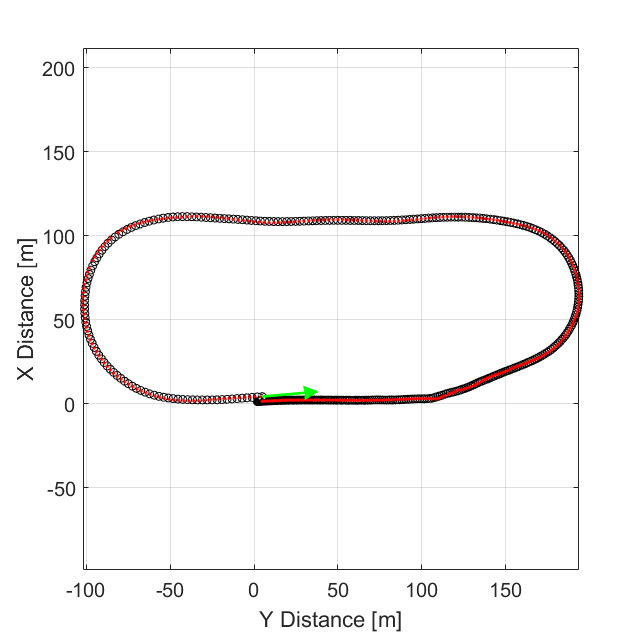

% %% Open the Simulink model and start the simulation
modelName = 'MPC_Controller';
open_system (modelName);
sim(modelName);

        The Simulink model consists of the following blocks:

**        1. Longitudinal Driver and Error Analysis: **

            This block has two purposes which are controlling the vehicle velocity and conducting Error Analysis. 

            To control the vehicle velocity, the vehicle reference position, direction, speed profile and the path curvatures are fed to a "Helper Path Analyzer" subsystem. This subsystem will compute the reference pose and velocity signals (outputs) based on the current pose and velocity of the vehicle. The current poses and velocity are feedback signals from the 3 DOF vehicle. 

            The output of the subsystem will be fed to a Longitudinal Driver which is a velocity controller which generates normalized acceleration and braking commands. The commands will be converted to velocity and fed later to the 3 DOF Vehicle Model and Model Predictive Controller. 

            To conduct an Error Analysis, the percentage error is found between the refrence position/velocity and the current position/velocity.

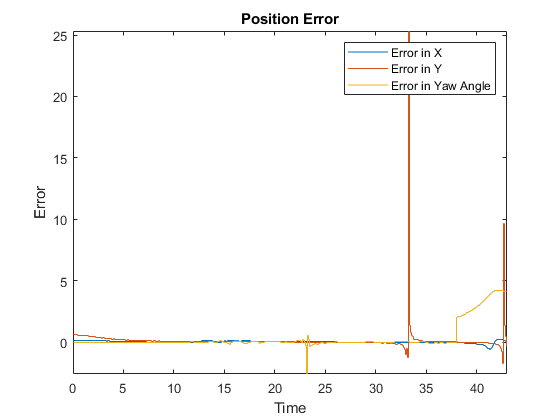

% Plot the position error
figure()
load("positionerror.mat")
plot(positionerror)
title('Position Error')
xlabel('Time')
ylabel('Error')
legend('Error in X','Error in Y','Error in Yaw Angle')
axis tight


% Plot the velocity error
figure()
load("VelocityError.mat")
plot(VelocityError)
title('Velocity Error')
xlabel('Time')
ylabel('Error')
axis tight

         2. **Vehicle Dynamics:** 

            This block consists of the 3 DOF Vehicle Model which models a rigid two-axle vehicle body and finds the longitudinal, lateral, and yaw motion (output). It enables closed loop simulation and takes the vehicle dynamics and aerodynamic into consideration. The inputs of this block are the velocity produced from the Longitudinal Driver and the steering angel produced from the Model Predictive Controller.

**          3. Scenario Reader: **

            This block takes the vehicle status (position, velocity, yaw angle and yaw rate) as an input from the  3 DOF Vehicle Model. The status will be updated as the vehicle moves along the path. Moreover, it reads the path from the driving scenario object created previously 'scenario' and outputs the vehicle position and the lane boundaries. In this example, only the lane boundaries is needed which is passed to a Vision Detection Generator  Sensor Block. This block takes the lane boundaries and models the field of view from camera measurements taken by a vision sensor mounted on the vehicle. Based on these measurements, the lateral deviation, the relative yaw angle between the path and the vehicle, path curvature, and curvature derivative are found. These variables will be fed later to the Model Predictive Controller. 

**        4. Model Predictive Controller Block (MPC): **

            Model predictive control (MPC) is a discrete-time multi-variable control architecture which predicts future plant behavior and computes the optimal control actions accordingly. It provides several blocks such as lane-keeping assistance which will be used in this example. The inputs of this block are the Lane Sensor Bus (Scenario Reader Output) and the velocity (Longitudinal Driver Output). This block contains two sub-blocks which are: Lane Center, and Lane Keeping Controller.

*a.  Lane Center:*

            This sub-block aims at finding the path centerline and curvature using the path boundaries obtained from the Scenario Reader. This is done by offsetting the lane boundaries variables toward the centerline. Each lane is weighted by the strength of the detection. The averaged output is passed to the Lane Keeping Controller. Moreover, the curvature is predicted for 10 m ahead, which improves the controller performance.

*b. Lane Keeping Controller:*

            This controller keeps the vehicle traveling along a a straight or curved path by changing the steering angle to reduce both the lateral deviation and relative yaw angle to zero. It takes the output results of the Lane Center along with velocity (Longitudinal Driver Output). It outputs an optimal control actions while satisfying steering angle constraints using Adaptive Model Predictive Control (MPC). This signal will be fed to the 3 DOF Vehicle Model.

**        5. Visualization: **

            Two representations are used to simulate the vehicle motion which are Unreal Engine and the XY plotter. The input of this block is the feedback signal from the 3 DOF vehicle. Moreover, the XY plotter takes the reference position as an input to show how the vehicle is following the reference path.

## `Parameters Estimation`

            The 'parameterEstimation' function aims at estimating the optimum vehicle and environment parameters such as: the vehicle mass, the wheel base, location of the center of gravity, axle height, front/rear tire corner stiffness and coefficient of friction. Moreover, lateral controller parameters are estimated such as the steering agressiveness, min/max steering angle and prediction horizon using Least Square Optimization Method. This is done by considering the vehicle reference position as the desired output. Then the function will continue in changing these parameters to match between the simulated and desired outputs. In other words, the function will find the optimum vehicle parameters that will make the vehicle follows the desired path. The simulated results will be obtained from the Simulink Model where the function will run the simulation repeatedly for each set of parameters. The function returns estimated parameter values and estimation termination information.

%% Load the Reference positions

% The positions are saved into mat file during the 
% simulation. These values are used in the parameters 
% estimation
load('xref.mat');
load('yref.mat');

            Note: This process may take long time. To start running the parameter estimation, execute the following function:

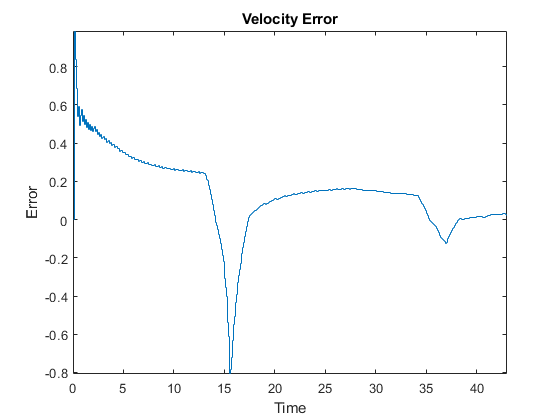

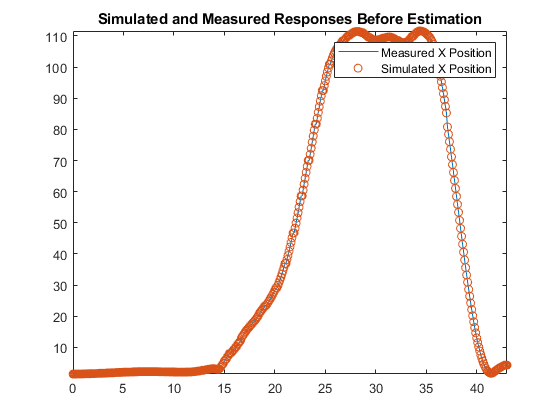

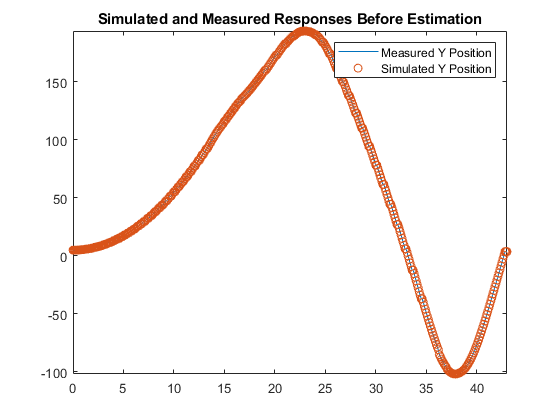

%% Paramaters Estimation
[pOpt, Info] = parameterEstimation (xref,yref);